**File ...816 contains the data concerning "E, F, G"**

**File ...818 contains the data concerning "A, B, C, D"**

clear all; close all; clc;
cd '/Users/erusconi/Desktop/EmmaStuff/Briggsae and Tropicalis /Day 1 /Skeleton'
fds = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 

skelFile = fds.Files;

numFiles = length(skelFile);


% Loop over all files reading them in and plotting them.
for k = 1 : numFiles
    name = sprintf('dataSet_%d', k);   
    fprintf('Now reading file %s\n', skelFile{k});

    trajData_struc.(name) = h5read(skelFile{k},'/trajectories_data');
    blobFeats_struc.(name) = h5read(skelFile{k},'/blob_features');
    skeleton_struc.(name)= h5read(skelFile{k}, '/skeleton');
end 

Now reading file /Users/erusconi/Desktop/EmmaStuff/Briggsae and Tropicalis /Day 1 /Skeleton/metadata_skeletons816.hdf5
Now reading file /Users/erusconi/Desktop/EmmaStuff/Briggsae and Tropicalis /Day 1 /Skeleton/metadata_skeletons818.hdf5



cd '/Users/erusconi/Desktop/EmmaStuff/Briggsae and Tropicalis /Day 1 /FeaturesN'
fds = fileDatastore('*.hdf5', 'ReadFcn', @importdata);   % here you can specify which ever file type you prefer 

featuresFile = fds.Files;

numFiles = length(featuresFile);

% Loop over all files reading them in and plotting them.
for k = 1 : numFiles
    name = sprintf('dataSet_%d', k);    
    fprintf('Now reading file %s\n', featuresFile{k});

    time_series.(name)= h5read(featuresFile{k}, '/timeseries_data');
end  

Now reading file /Users/erusconi/Desktop/EmmaStuff/Briggsae and Tropicalis /Day 1 /FeaturesN/metadata_featuresN816.hdf5
Now reading file /Users/erusconi/Desktop/EmmaStuff/Briggsae and Tropicalis /Day 1 /FeaturesN/metadata_featuresN818.hdf5


cd('..')
cd('/Users/erusconi/Desktop/EmmaStuff/Briggsae and Tropicalis ')

**Split wells in camera**

Video species_run1_prestim_20201130_150151.22956818

- MY23  well: A

- JU1373     well: B

- QX1410     well: C

- 58,00 NIC   well: D

 Video species_run1_prestim_20201130_150151.22956818

- N2    well: E

- CB4856   well: F

- VX34   well: G

Frame 1 extracted through python on "/Users/erusconi/Frames Extraction + Overlay.ipynb" 

% frame0 = imread("frame0.jpg");
% image(frame0)
% hold on 
% well_coordi = cell(2,1); 
% 
% [well_coordi{1},well_coordi{2}] = meshgrid(50:745:3050);
% plot(well_coordi{1},well_coordi{2},'.r')
% plot(well_coordi{1}(2,4),  well_coordi{2}(2,4),'.y')        % index guardando immagine 

Choose coordinates for specific well

NOOOOOO! USE FEATURESN TO SEPERATE INIDIVDUALS THROUGH THE WELL NUMBER 

example time_series.well_name(:,1) = 'A' '2' ' ' (3x1) 

name = sprintf('dataSet_%d', 1);
timeSeries1_cell = struct2cell(time_series.(name)); 
index_i = find((timeSeries1_cell{3}(1,:) == 'F') & (timeSeries1_cell{3}(2,:) == '1'))'; %| (timeSeries1_cell{3}(2,:) == '2') | (timeSeries1_cell{3}(2,:) == '3') | (timeSeries1_cell{3}(2,:) == '4')

**Select Skeletons interested in **

code taken from Self_BehaviourlSpaceReconstruction (first part) 

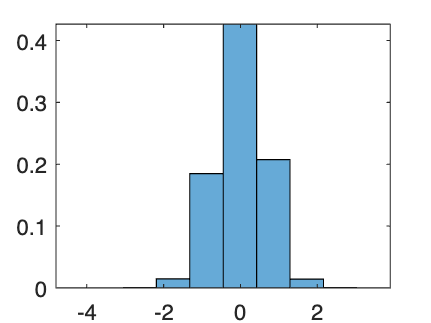

x = []; 
y = []; 
ang_skel_i = []; 
v = [1 0];

for i=1:size(index_i,1)
    x = [x; skeleton_struc.(name)(1,:,index_i(i))];
    y = [y; skeleton_struc.(name)(2,:,index_i(i))];
end 

[angleArray, meanAngles] = makeAngleArray(x, y);

% check angle distribution 
figure
histogram(angleArray,10,Normalization="probability")
axis tight

Angle distribution for both cases looks different for NPR1 case. Check for possible mistakes. 

% cov_ang = ang_skel*flip(ang_skel)';     % flipping the order of the worm segments because I want to get the same matrix as Greg 
cov_ang_i = cov(angleArray,0,'omitrows');


h = figure; 
imagesc(cov_ang_i) % displays a matrix as a color map 
colormap(parula) % color scale selection 
cbar = colorbar % insert colorbar

cbar =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-0.2283 0.7484]
    FontSize: 9
    Position: [0.8482 0.1095 0.0286 0.8155]
       Units: 'normalized'

  Show all properties


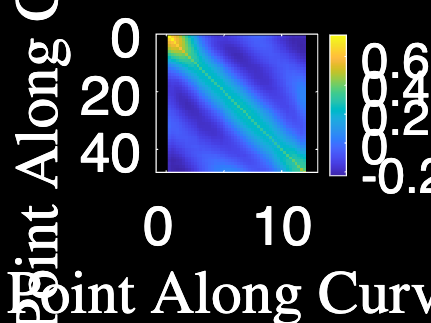

axis([0 size(cov_ang_i,1) 0 size(cov_ang_i,1)]);
set(gca,'XTickLabel',0:5:45)
xlabel('Point Along Curve',Interpreter='latex')
ylabel('Point Along Curve',Interpreter='latex')
axis equal
cbar.Color = 'w';
set(gca,'FontSize',25)
darkBackground(h)
set(gcf, 'inverthardcopy', 'off')
print("covarianceMatrixPoster",'-dpdf')

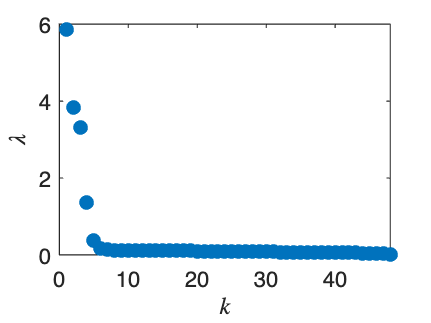

[eigenvectors_i,D_i] = eig(cov_ang_i); 
eigenvalues_i = diag(D_i); 

[eigenvalues_i,ind_i] = sort(eigenvalues_i,'descend');    % check the eigenvalues 
eigenvectors_i = eigenvectors_i(:,ind_i);

sigma_i = sum(eigenvalues_i);
sigma_k_i = []; 

for k=1:size(eigenvectors_i,1)
    sigma_k_i = [sigma_k_i; sum(eigenvalues_i(1:k)/sigma_i)]; 
end 

figure 
plot(eigenvalues_i,'.',MarkerSize=20)
xlabel('$k$',Interpreter='latex')
ylabel('$\lambda$',Interpreter='latex')

What does the eigenvalue value difference between the three species mean? 

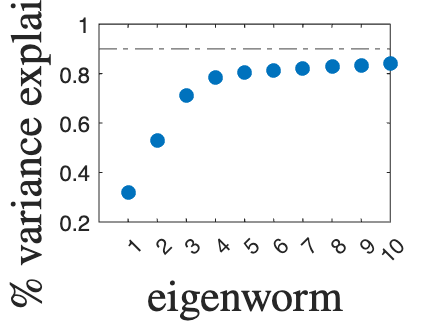

max_eigen = 10; 

figure 
plot([1:max_eigen],sigma_k_i(1:max_eigen),'.',MarkerSize=20)
hold on 
yline(0.9,'-.')
xticks(1:max_eigen)
xlabel('eigenworm',Interpreter='latex',FontSize=20)
ylabel('$\%$ variance explained',Interpreter='latex',FontSize=20)

`Plot of eigenworm projection `

hh = figure 

hh =   Figure (15) with properties:

      Number: 15
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [440 378 560 420]
       Units: 'pixels'

  Show all properties


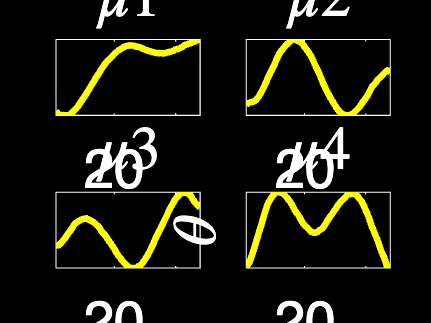

for i=1:4   % number of eigenworms plotted 
    subplot(2,2,i)
    plot(eigenvectors_i(:,i),'y',LineWidth=3)
    title(['$\mu $' num2str(i)],Interpreter="latex")
    axis tight 
    set(gca,'FontSize',25)
    set(gca,'YTick',[])
end 
xlabel('s',Interpreter='latex')
ylabel('$\theta $',Interpreter='latex')
set(gca,'FontSize',25)
darkBackground(hh)
set(gcf, 'inverthardcopy', 'off')
print("eigenwormsPoster",'-dpdf')

Projection of worm skeleton on first 4 eigenvectors 

EigenProj_i = cell(4,1);
meanEigenProj_i = zeros(4,48); 
angleArray = angleArray(all(~isnan(angleArray),2),:);
tic 
    for i=1:4
        for j=1:size(angleArray,1)
            EigenProj_i{i,1} = [EigenProj_i{i,1}; (angleArray(j,:)'.*eigenvectors_i(:,i))']; 
        end 
        meanEigenProj_i(i,:) = mean(EigenProj_i{i},1);
    end 
toc 

Elapsed time is 6.070622 seconds.


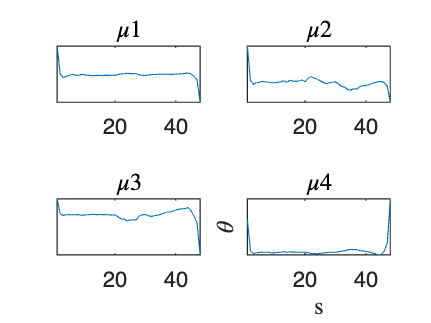

figure 
for i=1:4   % number of eigenworms plotted 
    subplot(2,2,i)
    plot(meanEigenProj_i(i,:))
    title(['$\mu $' num2str(i)],Interpreter="latex")
    axis tight 
    set(gca,'ytick',[])
end 
xlabel('s',Interpreter='latex')
ylabel('$\theta $',Interpreter='latex')

# Plots for grant 

**Panel a)**. Percentage variance accounted for, across all strains 

**Panel b)**. similarity and differences in eige porjections across strains (on MY23 eigenvectors) 

number_strains = 7; 
index_strain_i = cell(7,1);

% 818
% letter_ind = ['A', 'B', 'C', 'D']';
letter_ind = ['A', 'B', 'C', 'D']';

groups_incl = ['1', '2', '3','4'];
name = sprintf('dataSet_%d', 2);
timeSeries2_cell = struct2cell(time_series.(name)); 
for i = 1:size(letter_ind,1) % loop through the letters 
    letter = letter_ind(i);
    for k=1:size(groups_incl,1)
        index_strain_i{i,1} = [index_strain_i{i,1}; find((timeSeries2_cell{3}(1,:) == letter) & (timeSeries2_cell{3}(2,:) == groups_incl(k)))']; 
    end 
end 

% 816
letter_ind = ['E','G','F']';
name = sprintf('dataSet_%d', 1);
timeSeries1_cell = struct2cell(time_series.(name)); 
for i = 1:size(letter_ind,1) % loop through the letters 
    letter = letter_ind(i);
    j = i+4;
    for k=1:size(groups_incl,1)
        index_strain_i{j,1} = [index_strain_i{i,1}; find((timeSeries1_cell{3}(1,:) == letter) & (timeSeries1_cell{3}(2,:) == groups_incl(k)))'];
    end 
end 

Compute angle for each strain 

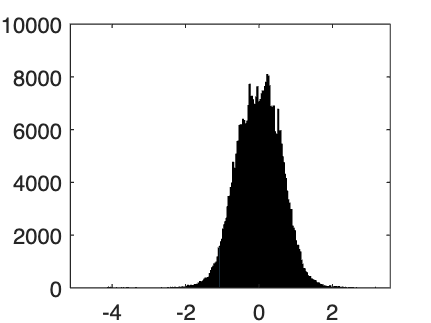

v = [1 0];

for i=1:size(index_strain_i,1) % loop through the strains 
    x = []; 
    y = []; 
    
    if i < 5
        name = sprintf('dataSet_%d', 2);
    else 
        name = sprintf('dataSet_%d', 1);
    end 

    for j=1:size(index_strain_i{i},1)
        x = [x; skeleton_struc.(name)(1,:,index_strain_i{i}(j))];
        y = [y; skeleton_struc.(name)(2,:,index_strain_i{i}(j))];
    end 
    
    [angleArray{i,1}, meanAngles] = makeAngleArray(x, y);
end 

figure 
histogram(angleArray{1})

**Compute covariance matrix for all and eigendecomposition **

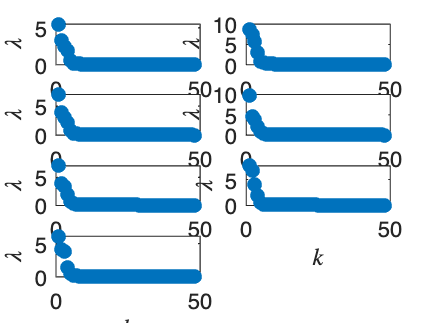

sigma_k_i = cell(size(index_strain_i,1),1);
for i=1:size(angleArray,1)
     
    cov_ang_i = cov(angleArray{i},0,'omitrows');

    [eigenvectors_i{i},D_i{i}] = eig(cov_ang_i); 
    eigenvalues_i{i} = diag(D_i{i}); 
    
    [eigenvalues_i{i},ind_i{i}] = sort(eigenvalues_i{i},'descend');    % check the eigenvalues 
    eigenvectors_i{i} = eigenvectors_i{i}(:,ind_i{i});
    
    sigma_i{i} = sum(eigenvalues_i{i});
    
    for k=1:size(eigenvectors_i{i},1)
        sigma_k_i{i} = [sigma_k_i{i}; sum(eigenvalues_i{i}(1:k)/sigma_i{i})]; 
    end 
    cov_ang_i = [];
end 

figure 
for i=1:size(index_strain_i,1)
    subplot(4,2,i)
    plot(eigenvalues_i{i},'.',MarkerSize=20)
    xlabel('$k$',Interpreter='latex')
    ylabel('$\lambda$',Interpreter='latex')
end 

**Panel a. **

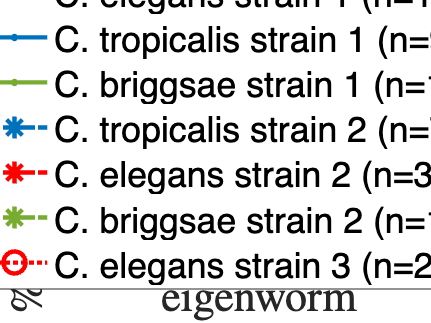

strain_name_1 = sprintf('C. elegans strain 1 (n=%d)', size(index_strain_i{1},1));
strain_name_2 = sprintf('C. tropicalis strain 1 (n=%d)', size(index_strain_i{2},1));
strain_name_3 = sprintf('C. briggsae strain 1 (n=%d)', size(index_strain_i{3},1));
strain_name_4 = sprintf('C. tropicalis strain 2 (n=%d)', size(index_strain_i{4},1));
strain_name_5 = sprintf('C. elegans strain 2 (n=%d)', size(index_strain_i{5},1));
strain_name_6 = sprintf('C. briggsae strain 2 (n=%d)', size(index_strain_i{6},1));
strain_name_7 = sprintf('C. elegans strain 3 (n=%d)', size(index_strain_i{7},1));
linS = {'-','-.',':'};
Mark = {'.','*','o'};
C = {'r',[0 0.4470 0.7410],[0.4660 0.6740 0.1880]};
max_eigen = 8; 
figure 

for i=1:size(index_strain_i,1)
    if i == 1 || i == 2 || i == 3
        j = 1; 
    end 
    if i == 4 || i == 5 || i == 6
        j = 2; 
    end 
    if i == 7
        j = 3; 
    end

    if i == 1 || i == 5 || i == 7
        ii = 1; 
    end 
    if i == 2 || i == 4
        ii = 2; 
    end 
    if i == 3 || i == 6
        ii = 3; 
    end 

    h(i) = plot([1:max_eigen],sigma_k_i{i}(1:max_eigen),'color',C{ii},'marker',Mark{j},'linestyle',linS{j},"LineWidth",2,MarkerSize=10);
    hold on 
    xticks(1:max_eigen)
    xlabel('eigenworm',Interpreter='latex',FontSize=20)
    ylabel('$\%$ variance explained','FontWeight','Bold',Interpreter='latex',FontSize=20)
    ylim([0 1])
end
xlim([1 max_eigen])
legend(h, { strain_name_1, strain_name_2, strain_name_3, strain_name_4, strain_name_5, strain_name_6, strain_name_7},Location="best")
set(gca,'fontsize',18)

Flip sign of {strains} showing flipped sign in (mode)

eigenvectors_i{1}(:,2) = -eigenvectors_i{1}(:,2); 
eigenvectors_i{2}(:,2) = -eigenvectors_i{2}(:,2); 
eigenvectors_i{3}(:,3) = -eigenvectors_i{3}(:,3);
eigenvectors_i{4}(:,3) = -eigenvectors_i{4}(:,3);

**Panel b. **

first 4 eigenworms for 7 strains 

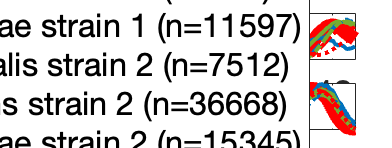

figure
% add a bit space to the figure
fig = gcf;
fig.Position(3) = fig.Position(3) + 550;

for i=1:4  
    subplot(2,2,i)
    
    for j=1:size(index_strain_i,1)
        
        STRAIN_NAME = { strain_name_1, strain_name_2, strain_name_3, strain_name_4, strain_name_5, strain_name_6, strain_name_7}; 
        if j == 1
            plot(eigenvectors_i{1}(:,i),'-r','DisplayName',STRAIN_NAME{j},LineWidth=7);
            str = sprintf('$\\mu_%d$', i);
            title(str,'FontWeight','Bold',Interpreter="latex",FontSize=15);
            axis tight 
            hold on 
        else 
            if j == 2 || j == 3
                k = 1; 
            end 
            if j == 4 || j == 5 || j == 6
                k = 2; 
            end 
            if j == 7
                k = 3; 
            end
        
            if j == 1 || j == 5 || j == 7
                ii = 1; 
            end 
            if j == 2 || j == 4
                ii = 2; 
            end 
            if j == 3 || j == 6
                ii = 3; 
            end 
            plot(eigenvectors_i{j}(:,i),'DisplayName',STRAIN_NAME{j},'color',C{ii},'linestyle',linS{k},"LineWidth",2,MarkerSize=10);
            str = sprintf('$\\mu_%d$', i);
            title(str,'FontWeight','Bold',Interpreter="latex");
            axis tight 
            hold on 
            set(gca,'ytick',[])
            set(gca,'fontsize',18)
        end 
    end   
end 
% add legend
Lgnd = legend('show');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
ylabel('Normalised Angle','FontWeight','Bold',Interpreter="latex",FontSize=18)
xlabel('Segment Number','FontWeight','Bold',Interpreter="latex",FontSize=18)

% set(gca,'FontWeight','Bold')

### Projection on MY23

eigenvectors_i{4} contains the vectors corresponding to MY23

EigenProj_i = cell(size(index_strain_i,1),4);
for i=1:size(angleArray,1)
    angleArray{i} = angleArray{i}(all(~isnan(angleArray{i}),2),:);      % clean all nana values 
end 

for j=1:size(index_strain_i,1) % loop through all species
    for i=1:4      % loop throguh first 4 modes  
        for k=1:size(angleArray{j},2)   % loop throguh all skeletons 
            EigenProj_i{j,i} = [EigenProj_i{j,i}; (angleArray{j}(k,:).*eigenvectors_i{4}(:,i))']; % projection on MY23 eigenvector
        end 
    end 
    for i=1:4
        meanEigenProj_i{j,i} = mean(EigenProj_i{j,i},1)';
    end
end 

figure 
for i=1:4
    for j=1:size(index_strain_i,1)
        subplot(2,2,i)
        g = plot(meanEigenProj_i{j,i});
        hold on 
        legend(STRAIN_NAME(j))
    end 
    plot(meanEigenProj_i{4,i},'-r', LineWidth=5);
    hold off 
    title(['$\mu $' num2str(j)],Interpreter="latex")
    axis tight 
    set(gca,'ytick',[])
    ylabel('Normalised Angle',Interpreter="latex")
end 